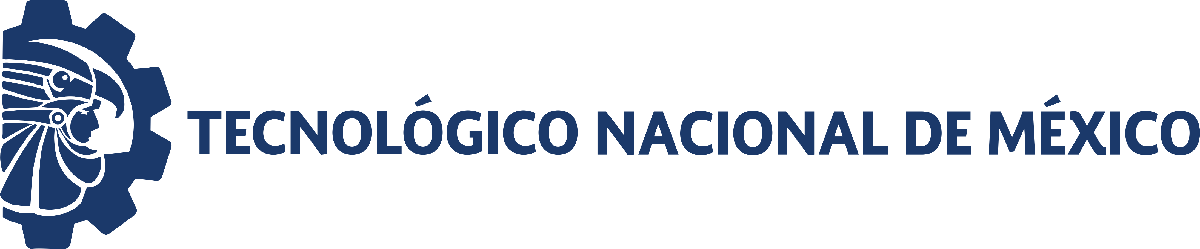                                 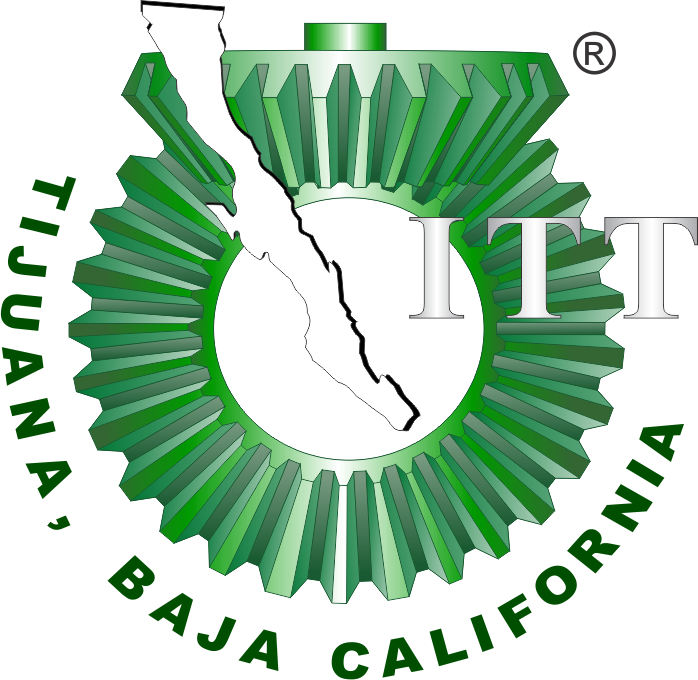

# Práctica 3: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

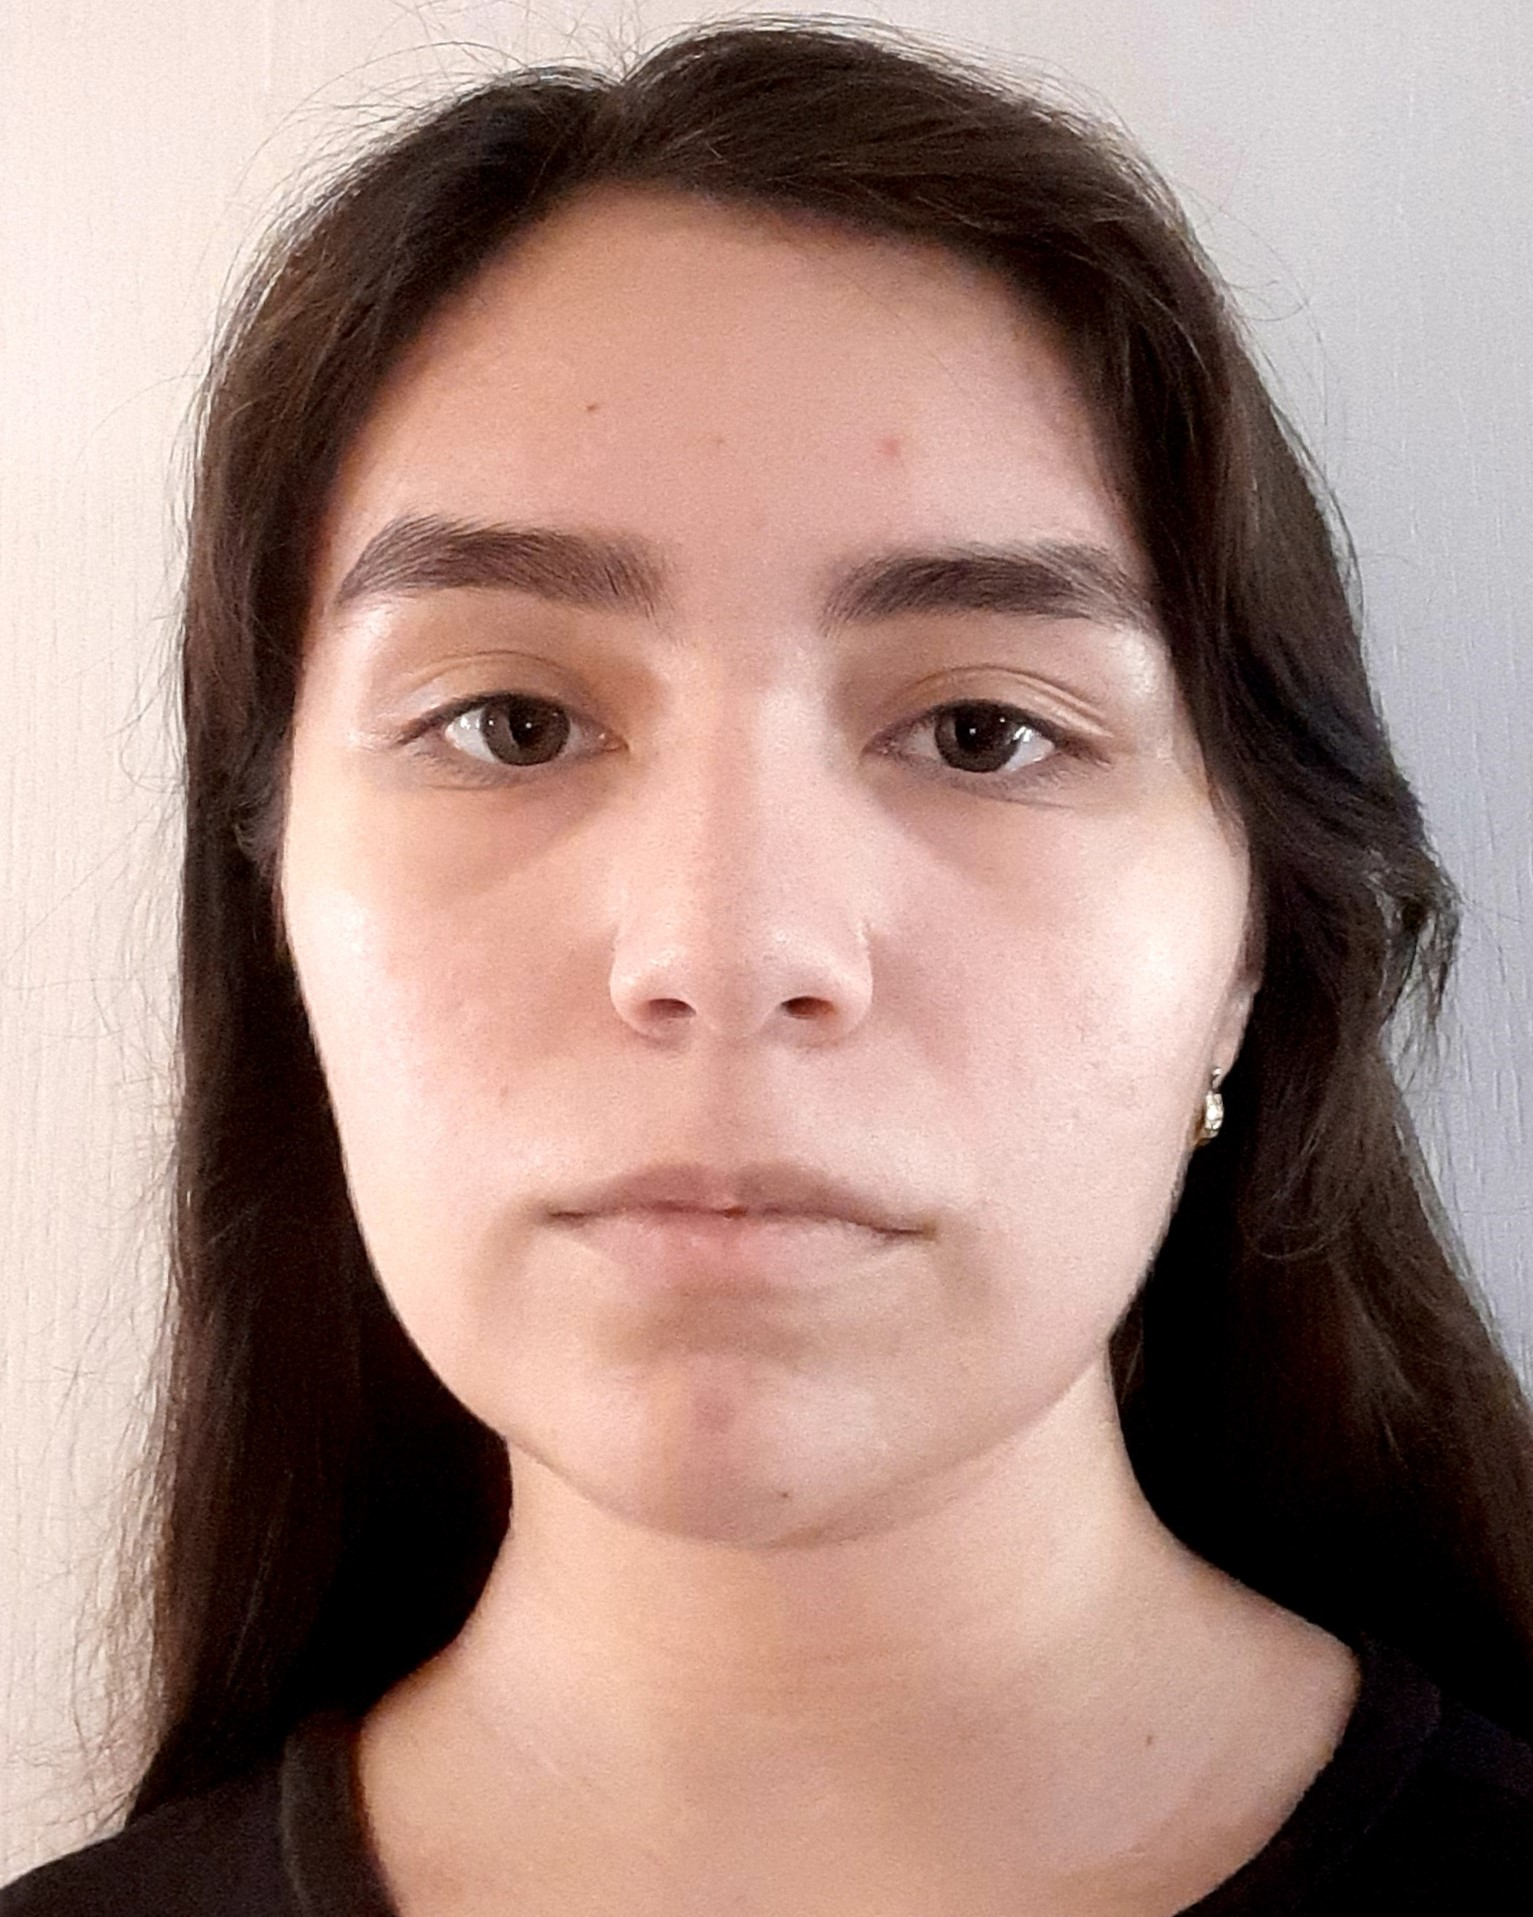

Nombre del alumno: Villa Camacho Abigail

Número de control: 22212276

Correo institucional: L22212276**@tectijuana.edu..mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema_circuito3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta en lazo abierto

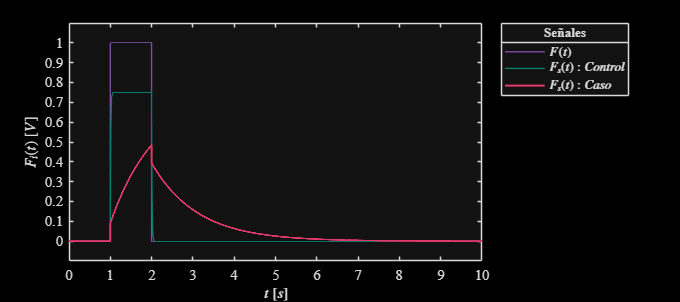

Signal = 'LazoAbierto';
x0 = sim(file,parameters);
%writematrix(x0.Ppa,'signal.xlsx');
plotsignals0(x0.t,x0.F,x0.Fs1,x0.Fs2,Signal)

## Respuesta en lazo abierto y lazo cerrado (PID)

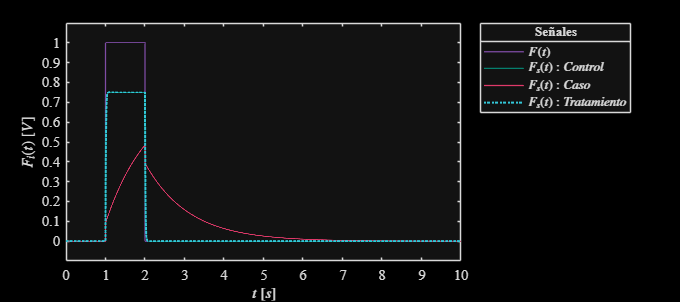

Signal = 'LazoCerrado'; %Step
x1 = sim(file,parameters);
plotsignals1(x1.t,x1.F,x1.Fs1,x1.Fs2,x1.Fs3,Signal)

## Función: Respuesta a las señales

function plotsignals0(t,F,Fs1,Fs2,Signal)
set(figure(),'Color','k')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [0.4980,0.2980,0.6471;
            0.0196,0.4980,0.4275;
            0.8745,0.2235,0.4118;
           ];
colororder(mycolors)

p = plot(t, F, '-', t, Fs1, '-', t, Fs2, '-','LineWidth', 1, 'MarkerIndices', 1:1000:length(t));
set(p(3), 'LineWidth', 1.5);
L = legend('$F(t)$', '$F_s(t): Control$','$F_s(t): Caso$', '$F_s(t): Entrada$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
title(L,'Señales', 'FontSize', 10);
xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$F_i(t)$ $[V]$','Interpreter','Latex','FontSize',11 )
xlim([0,10]); xticks(0:1:10);
ylim([-0.1,1.1]); yticks(0:0.1:1);

    exportgraphics(gcf,[Signal, '.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal, '.png'],'ContentType','vector')

end

function plotsignals1(t,F,Fs1,Fs2,Fs3,Signal)
set(figure(),'Color','k')
set(gcf,'units','centimeters','position',[1,1,18,8]) 
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [0.4980,0.2980,0.6471;
            0.0196,0.4980,0.4275;
            0.8745,0.2235,0.4118;
            0.2000,0.7804,0.8471; 
            1.0000,0.5529,0.0784;
            ];
colororder(mycolors)

p = plot(t, F, '-', t, Fs1, '-', t, Fs2, '-',t, Fs3, ':','LineWidth', 1, 'MarkerIndices', 1:1000:length(t));
set(p(4), 'LineWidth', 1.5);
L = legend('$F(t)$', '$F_s(t): Control$','$F_s(t): Caso$', '$F_s(t): Tratamiento$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
title(L,'Señales', 'FontSize', 10);
xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$F_i(t)$ $[V]$','Interpreter','Latex','FontSize',11 )
xlim([0,10]); xticks(0:1:10);
ylim([-0.1,1.1]); yticks(0:0.1:1);

    exportgraphics(gcf,[Signal, '.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal, '.png'],'ContentType','vector')

end